# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha:**

clc;
clear all;
close all;

# Tema 4. Ejercicio 5 - Texturas

El objetivo de este ejercicio la caracterización de texturas. Para ello, sobre imágenes con texturas diferentes, se obtendrán y compararán los valores de entropía, las matrices de coocurrencia en niveles de gris (GLCM) y estadísticas de las GLCM para diversos valores del vector de *offset*.

 1) Lectura de las imágenes.

% textures from http://www.cb.uu.se/~gustaf/texture/
imagenames = {'texture-stone.png','texture-pattern1.png','texture-linseeds.png', 'texture-canvas.png','texture-pattern2.png','texture-sand.png'};

textureImg = [];
for n = 1:length(imagenames)
    textureImg{n} = imread(imagenames{n});
end

2) **Entropía:** Calcule la entropía de las imágenes de patrones *textureImg* leídas en el paso anterior (usando la función `entropy)`, y ordénelas (usando la función `[MatrizOrdenada,SortedIndex] = sort(Matriz))`, en orden creciente de entropía (de la más baja a la más alta) y muéstrelas según dicho orden. ¿Qué imagen tiene la menor entropía y por qué? Justifique sus conclusiones.

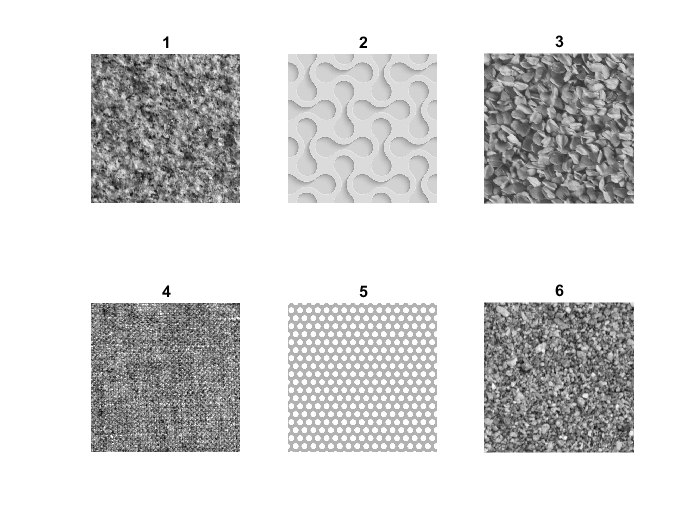

figure;
for n = 1:length(textureImg)
    subplot(2,3,n); imshow(textureImg{n}); title(n);
end

% guardamos las entropías de cada imagen en una lista
im_entropy = [];
for n = 1:length(textureImg)
    im_entropy(n) = entropy(textureImg{n});
end
disp(im_entropy);

    6.8046    4.7936    7.2660    5.9055    4.1983    6.5980



[sorted_matrix, sorted_index] = sort(im_entropy)

sorted_matrix =     4.1983    4.7936    5.9055    6.5980    6.8046    7.2660


sorted_index =      5     2     4     6     1     3


**La entropía mide aleatoriedad de la imagen, es decir, su desorden. Por lo que, la imagen 5 es la que menos entropía presenta ya que es la más ordenada y sigue un mismo patrón por toda ella. Además, es una característica que se puede apreciar visualmente.**

3) **GLCM (Matriz de coocurrencia de niveles de gris): **Lea la ayuda de la función `graycomatrix` para entender todos sus parámetros ([https://es.mathworks.com/help/images/ref/graycomatrix.html](https://es.mathworks.com/help/images/ref/graycomatrix.html)). Defina ***offsets*** para las siguientes direcciones (0º, 45º, 90º, 135º) de longitud de lado = 5 (len=5) y utilícelos para crear un conjunto de matrices de coocurrencia (GLCMs), usando la función de `graycomatrix`, para las texturas: '`texture-linseeds.png'` y `'texture-pattern2.png'`. Puede serle útil consultar el código del ejemplo "**Calcular GLM utilizando cuatro desfases diferentes" **de la ayuda de la función `graycomatrix`. 

len = 5;
% P = [row_offset, col_offset]
% P = [0 1] hace referencia un pixel más a la derecha (0º)
%           0     45    90    135
offsets = [0 1; -1 1; -1 0; -1 -1];

% co-ocurrence matrix of texture-linseeds.png (imagen 3 de la lista textureImg)
[glcms1, texture1] = graycomatrix(textureImg{3}, 'Offset', offsets); 
glcms1(:,:,1)

ans =            0           0           0           0           0           0           0           0
           0        9880        2134           0           0           0           0           0
           0        2109       65478        7096         145           0           0           0
           0           0        7148       69519        8318         135           0           0
           0           0          87        8433       63111        6665          12           0
           0           0           0          85        6716       51012        2882           0
           0           0           0           0           6        2909       17236          22
           0           0           0           0           0           0          22          40


glcms1(:,:,2)

ans =            0           0           0           0           0           0           0           0
           0        8742        3220          47           0           0           0           0
           0        3205       59856       10219        1292         127           0           0
           0          24       10746       61466       11495        1256          25           0
           0           0         818       12457       54738        9830         346           0
           0           0          58         747       10462       44474        4773           0
           0           0           0          20         172        4958       14954          36
           0           0           0           0           0           2          34          26


glcms1(:,:,3)

ans =            0           0           0           0           0           0           0           0
           0        9875        2131           3           0           0           0           0
           0        2120       64911        7557         260           3           0           0
           0           0        7648       68457        8797         251           0           0
           0           0         141        8916       62094        7142          23           0
           0           0           0         152        7131       50114        3244           0
           0           0           0           0          16        3238       16892          22
           0           0           0           0           0           0          22          40


glcms1(:,:,4)

ans =            0           0           0           0           0           0           0           0
           0        9467        2517           0           0           0           0           0
           0        2528       63393        8603         194           0           0           0
           0           0        8475       66395        9979         175           0           0
           0           0         293        9753       60488        7639           5           0
           0           0           1         193        7503       49730        3113           0
           0           0           0           0           7        3077       17013          22
           0           0           0           0           0           0          22          40


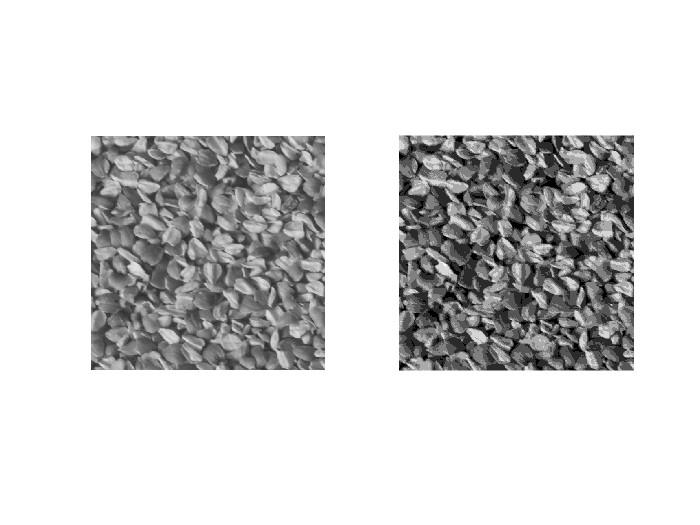

figure;
subplot(1,2,1); imshow(textureImg{3});
subplot(1,2,2); imshow(rescale(texture1));

% co-ocurrence matrix of texture-pattern2.png (imagen 5 de la lista textureImg)
[glcms2, texture2] = graycomatrix(textureImg{5}, 'Offset', offsets); 
glcms2(:,:,1)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           2           1           0
           0           0           0           0           2      190907        5170        2304
           0           0           0           0           1        5269        2425        4606
           0           0           0           0           0        2184        4707      113622


glcms2(:,:,2)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           2           0           1
           0           0           0           0           3      187657        5306        5214
           0           0           0           0           0        5874        1655        4754
           0           0           0           0           0        4502        5306      110351


glcms2(:,:,3)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           1           2           0
           0           0           0           0           3      191056        5195        2281
           0           0           0           0           0        5577        1852        4869
           0           0           0           0           0        1776        5231      113357


glcms2(:,:,4)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           1           0           2
           0           0           0           0           3      187654        5428        5074
           0           0           0           0           0        5784        1625        4876
           0           0           0           0           0        4617        5212      110349


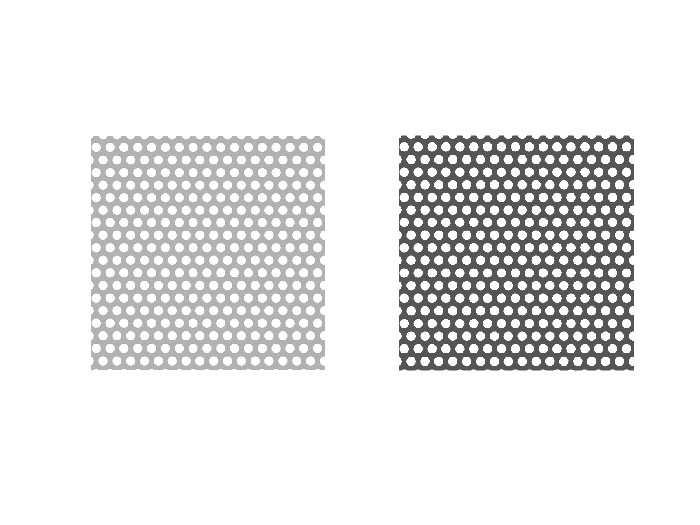

figure;
subplot(1,2,1); imshow(textureImg{5});
subplot(1,2,2); imshow(rescale(texture2));

4) Muestra la imagen de la primera **GLCM** con colores escalados. Para ello puede adaptar el código siguiente:

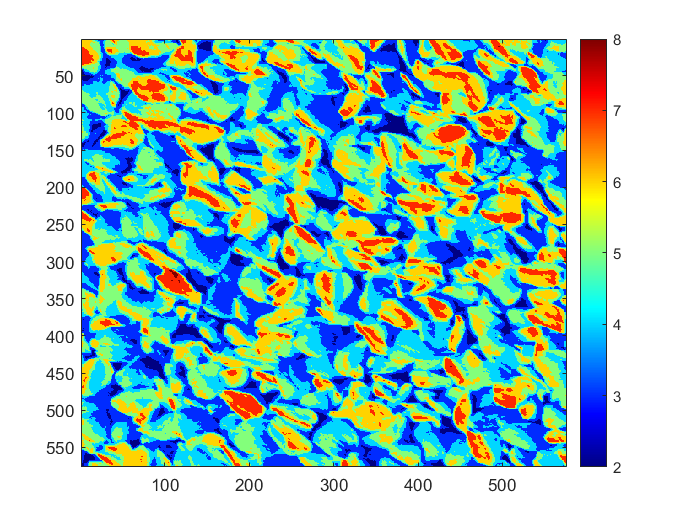

figure;
imagesc(texture1); colormap jet; colorbar;

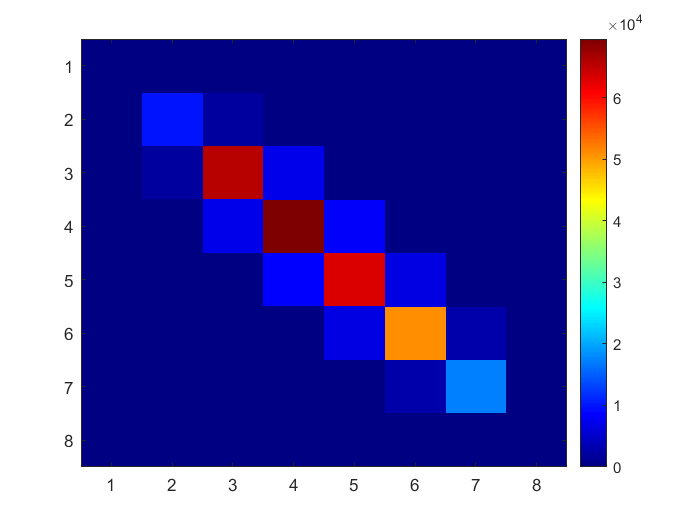

figure;
imagesc(glcms1(:,:,1)); colormap jet; colorbar;

% imagesc(glcm)
% colormap jet
% colorbar

5) **Opcional. **Obtenga estadísticos de la GLCM utilizando la función `graycoprops` para las imágenes `'texture-linseeds.png'` y `'texture-pattern2.png` para varios vectores de offset diferentes. Visualice en función del offset uno de los siguientes estadísticos: `Contrast, Correlation, Energy, Homogeneity`.